# **Actividad 1 - Mecanismo Articulado**

**Métodos Numéricos Aplicados 1**

***Ingeniería Matemática y Computación***

UNIR

COHORTE 2023-2024

*Javier Blanco*

## Planteamiento

Se tiene el siguiente mecanismo articulado (*ver figura*) cuya relación geométrica entre los ángulos $\alpha$ y $\beta \;$viene dada por la siguiente ecuación:


$${\left(d-a\;\cos \alpha -b\;\cos \beta \right)}^2 +{\left(a\;\sin \alpha +b\;\sin \beta \right)}^2 -c^2 =0$$


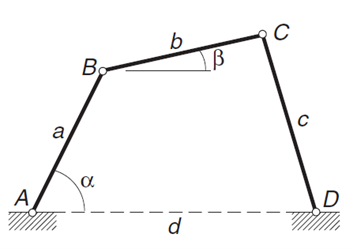

Tras varios ensayos experimentales se han logrado extraer los valores de la posición de $\beta$ con respecto a $\alpha$ entre los brazos AB y BC, dando como resultado la siguiente tabla:

data = load('input_data.mat', 'data').data;
data = array2table(data);
data

data = 2x7 table
    data1     data2     data3     data4     data5     data6     data7 
    ______    ______    ______    ______    ______    ______    ______

         0         5        10        15        20        25        30
    1.6595    1.5434    1.4186    1.2925    1.1712    1.0585    0.9561


Sabiendo que la sección AB gira a una velocidad angular constante de **25 rad/s**, y la relación entre la velocidad de angular de la sección BC viene dada por:


$$\frac{d\beta }{\textrm{dt}}=\frac{d\beta }{d\alpha }*\frac{d\alpha }{\textrm{dt}}$$


Se trata de calcular la velocidad ángular $\frac{d\beta }{\textrm{dt}}$ del brazo BC.

## Tarea 1. Discretización

Uso de diferencias finitas progresivas y regresivas de orden 2 para los puntos correspondientes $\alpha =0º\;$  y $\beta =30º$  respectivamente, y diferencia central de orden 2 para los puntos intermedios de la tabla.

***Solución:***

El uso de diferencias finitas implica discretizar el problema, de tal forma que podamos aproximarnos al calculo de la velocidad angular de $\beta$ con respecto a $\alpha$ dado que además una solución analítica en este contexto resulta muy compleja. 

Puesto que las diferencias solicitadas en esta actividad son de segundo orden, hemos de aproximar la solución al segundo término de expansión de la serie de Taylor, por lo tanto tendríamo que:


$$\[
f(x + h) = f(x) + hf'(x) + \frac{h^2}{2}f''(x) + \frac{h^3}{6}f'''(x) + \ldots
\]
$$


Así pues, nuestras diferencias finitas progresiva, regresiva y central vendrían dadas por las siguientes expresiones:


$$\(f'(x) = \frac{{4f(x+1) - 3f(x) - f(x+2)}}{{2h}}\)


\(f'(x) = \frac{{3f(x) - 4f(x-1) + f(x-2)}}{{2h}}\)


\(f'(x) = \frac{{-f(x+2) + 8f(x+1) - 8f(x-1) + f(x-2)}}{{12h}}\)

$$


Para el cálculo de las diferencias finitas se ha desarrollo la función **finite_diff.m **que muestra a continuación:

El criterio de paso h fue determinado de la siguiente forma:

Desde el script llamado **articulated_arm.m** se ejecuta el siguiente código:

clear;clc
format long;
%Upload data

data = load('input_data.mat', 'data');
array_size = size(data.data);
n = array_size(2);

low_boundary = data.data(1,1); %alpha = 0
high_boundary = data.data(1,n);
h = (high_boundary - low_boundary) / (n - 1);
alphas = data.data(1,:);
bethas = data.data(2,:);
dadt = 25.0;

%transform bethas radians into degrees
bethas_deg = rad2deg(bethas);

% PART 1
y_1 = finite_diff(bethas_deg,n,h,'forward');
y_2 =  finite_diff(bethas_deg, n, h, 'backward');
y_n =  finite_diff(bethas_deg, n, h, 'central');

dB = y_n;
dB(1,1) = y_1;
dB(1,n) = y_2;

dBdt = dB*dadt;

T = array2table([alphas' bethas', bethas_deg' dBdt(1,:)'], ...
    "VariableNames", ...
    {'Alpha (degree)','Betha (radians)', 'Betha (degree)', 'dB/dt (rad/seg)'});

disp(T);

    Alpha (degree)    Betha (radians)     Betha (degree)      dB/dt (rad/seg) 
    ______________    _______________    ________________    _________________

           0              1.6595         95.0823461019601    -32.0140168029346
           5              1.5434         88.4303061004913    -35.5663551327459
          10              1.4186         81.2797928172586     -36.261066459342
          15              1.2925         74.0547950206589    -35.6737847193329
          20              1.1712          67.104816965722     -33.649333843204
          25              1.0585         60.6475826145976    -31.0543124960907
          30              0.9561          54.780494792458    -27.8600727882363



El perfil de velicidad angular $\frac{d\beta }{\textrm{dt}}$ es de negativa, indicando con ello que el sentido del movimiento de brazo BC es horario. 

También se observa que el pefil de velicidad responde a una parabola convexa, tal como puede verse en la gráfica resultante:

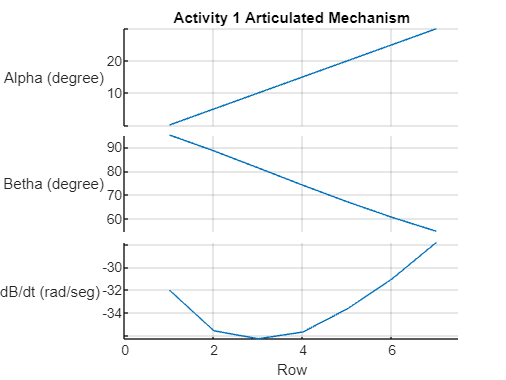

fig_table = array2table([alphas', bethas_deg' dBdt(1,:)'], ...
"VariableNames", ...
    {'Alpha (degree)','Betha (degree)', 'dB/dt (rad/seg)'});
stackedplot(fig_table);

xlim([0, 7.50])
% ylim(dBdt, [-37, -25])
grid on
title("Activity 1 Articulated Mechanism")

## Tarea 2. Interpolaciones de Lagrange

Para esta tarea se pide obtener el valor del ángulo $\beta$ en radiantes para $\alpha =12º$. Con los valores $\alpha \;$previos y posteriores conocidos, se pude realizar una interpolación lineal (grado 1) utilizando polinomios de Lagrange. 

*Solución:*

A efectos del presente informe, se ha desarrollado un algoritmo para el cálculo de los coeficienres del polinomio de Lagrange en cualquier grado. El algoritmo responde a una función llamada **lagrange_interpolation** como se muestra a continuación:

Por valores de entrada se han de incluir las corrdenadas de los vectores x e y, el grado del polinomio y los puntos t del vector x donde el polinomio será evaluado. 

Para responder a la peticoión de esta tarea se aplica el siguiente código:

betha_interpolation = lagrange_interpolation(alphas, bethas, 1, 12);
disp(['Betha value at Alpha = 12º: ', ...
    num2str(betha_interpolation,'%.8f'), ' radians']);

Betha value at Alpha = 12º: 1.36792894 radians


## Tarea 3. Interpolación polinomial

En esta ocasión se pide calcular la derivada segunda de la posición del ángulo $\beta$ con respecto a $\alpha$ en el punto $a=12º$ considerando los tres puntos más cercanos, es decir: 5, 10 y 15º. 

***Solución:***

Para ello, evaluaremos el polinomio de interpolación polinomial en los 3 puntos más cercanos y posteriormente calcularemos su segunda derivada. Sabiendo además la relación: 


$$\frac{d\beta }{\textrm{dt}}=\frac{d\beta }{d\alpha }*\frac{d\alpha }{\textrm{dt}}$$
 

podríamos calcular la aceleración angular del brazo BC mediante el siguiente código:

interpolation_point = 12;
[~, nearest_indexes] = mink(abs(alphas - interpolation_point), 3);
nearest_alphas = alphas(nearest_indexes);

[lagrange_coeffs, lagrange_err] = lagrange_interpolation(alphas, bethas, 2, nearest_alphas);
lagrange_second_derivative_point = polyder(polyder(lagrange_coeffs));
lagrange_velocity = (polyder(lagrange_coeffs))*dadt; % just because of the relation dBdt = dBda*dadt
lagrange_acceleration = polyder(lagrange_velocity);

[newton_coeffs, newton_err] = newton_interpolation(alphas, bethas, 2, nearest_alphas);
newton_second_derivative_point = polyder(polyder(newton_coeffs));
newton_velocity = (polyder(newton_coeffs))*dadt; % just because of the relation dBdt = dBda*dadt
newton_acceleration = polyder(newton_velocity);

results_table = array2table( ...
    [lagrange_second_derivative_point, newton_second_derivative_point, ...
    lagrange_acceleration, newton_acceleration], ...
    "VariableNames", {'f 2nd Lagrange', 'f 2nd Newton', ...
                      'Lagranges (rad/seg^2)', ...
                      'Newtons (rad/seg^2)'});

disp(results_table);

    f 2nd Lagrange    f 2nd Newton    Lagranges (rad/seg^2)    Newtons (rad/seg^2)
    ______________    ____________    _____________________    ___________________

        2.8372           2.8546               70.93                  71.365       



para esta ultima implementación se han utilizado tanto la interpolación de Lagrange como la de Newton, ambas vistas en el tema 3 de esta asignatura. 

## REFERENCIAS

- Maas, M. 2020. Apuntes de Diferencias Finitas. Disponible en: [http://cms.dm.uba.ar/academico/materias/2docuat2020/Analisis_Numerico/apunte.pdf](http://cms.dm.uba.ar/academico/materias/2docuat2020/Analisis_Numerico/apunte.pdf)

- Departamento de Matemática Aplicada y Ciencias de la computación. Diferencias Finitas. Universidad de Cantabria. Disponible en: [https://www.giematic.unican.es/funciones-de-una-variable-segunda-parte-2/diferencias-finitas/](https://www.giematic.unican.es/funciones-de-una-variable-segunda-parte-2/diferencias-finitas/)

## ANEXOS

- Version preliminar de la velocidad angular de Beta. 

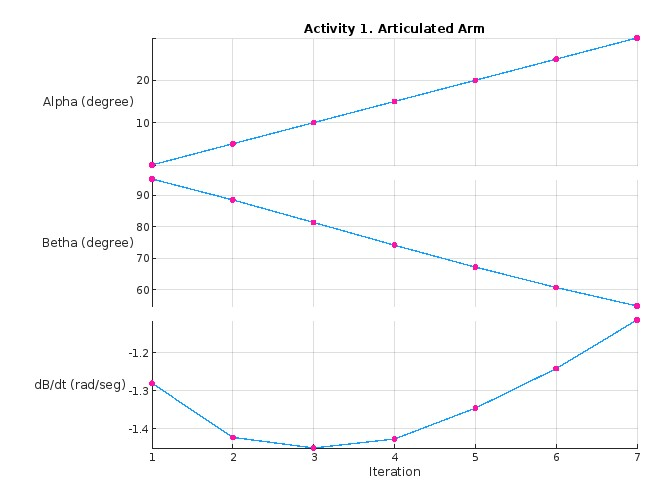

- Interpolación de Newton: